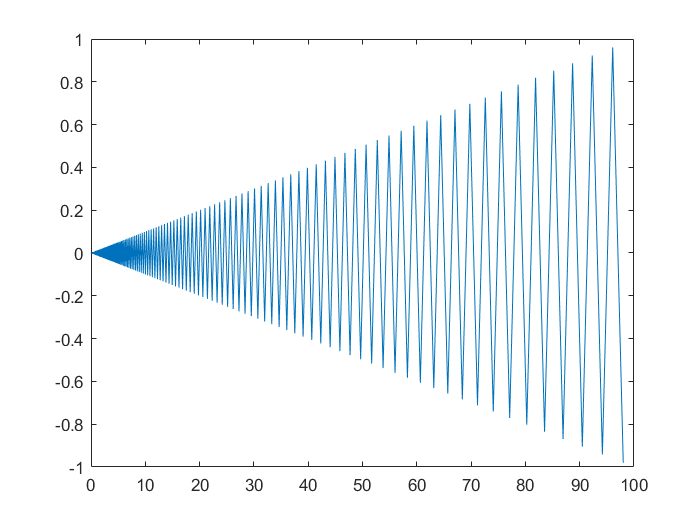

clc
clear all

syms x1 x2 t;
f = x1 ^ 2 / 2 + 50 * x2 ^ 2;
x = [100; 1];
epsilon = 1e-8;
x1_ax = [];
x2_ax = [];
f_ax = [];

d = -[diff(f,x1);diff(f,x2)];
flag = 1;
k = 0; 
while(flag)
    d_temp = subs(d,x1,x(1));      
    d_temp = subs(d_temp,x2,x(2));
    nor = norm(d_temp);
    if(nor >= epsilon)
        x_temp = x + t * d_temp;
        f_temp = subs(f,x1,x_temp(1));
        f_temp = subs(f_temp,x2,x_temp(2));
        h= diff(f_temp,t);
        t_temp = solve(h);
        x = x + t_temp * d_temp;
        x = double(x);
        x1_ax = [x1_ax, x(1)];
        x2_ax = [x2_ax, x(2)];
        f_ax = [f_ax, double(subs(subs(f,x1,x(1)),x2,x(2)))];
        k = k + 1;
    else
        flag=0;
    end
end
plot(x1_ax,x2_ax)

plot(log(f_ax))

错误使用 plot
向量长度必须相同。